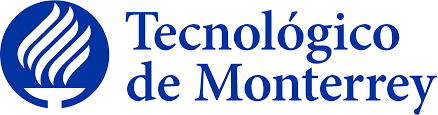

## Implementación de robótica inteligente (TE3002B)

## Evaluación 11.1 (Trayectorias en lazo abierto)

### Pamela Hernández Montero A01736368

**1. Implementar **el código requerido para generar las siguientes trayectorias a partir del tiempo y de las velocidades angulares y lineales en un plano 2D, según corresponda. La altura de cada letra debe ser de **3m.**, el ancho puede ser ajustable **a criterio propio** y la separación entre cada letra debe ser de **0.5m.**

Para esta primera parte, decidí utilizar el código "Differential drive vehicle following waypoints using the Pure Pursuit algorithm" que usa landmarks debido a que proporciona un enfoque facil y rapido para la navegación de vehículos diferenciales a través de una serie de puntos de referencia predefinidos en este caso los waypoints. 

Primero, se definen las características del vehículo diferencial, incluyendo el radio de las ruedas (R) y la distancia entre las ruedas (L). A continuación, se crean los parámetros de la simulación, que incluyen el tiempo de muestreo (sampleTime), el vector de tiempo (tVec) y la pose inicial del vehículo (initPose), que define su posición y orientación inicial en el espacio de simulación.

En este caso, decidí que se encontraría inicialmente en el punto (0,0) y debido a que la letra es una 'P', su orientación sería *π*/2, que equivale a 90 grados, facilitando su primer movimiento.

%% Define Vehicle
R = 0.02;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:205;       % Time array
initPose = [0;0; pi/2];        % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

Para definir los waypoints hice uso de la herramienta Suite Calculadora de Geogegra debido a que me permite trazar puntos ayudandome a definir como trazar cada letra considerando la altura de cada letra y su separación entre ellas.

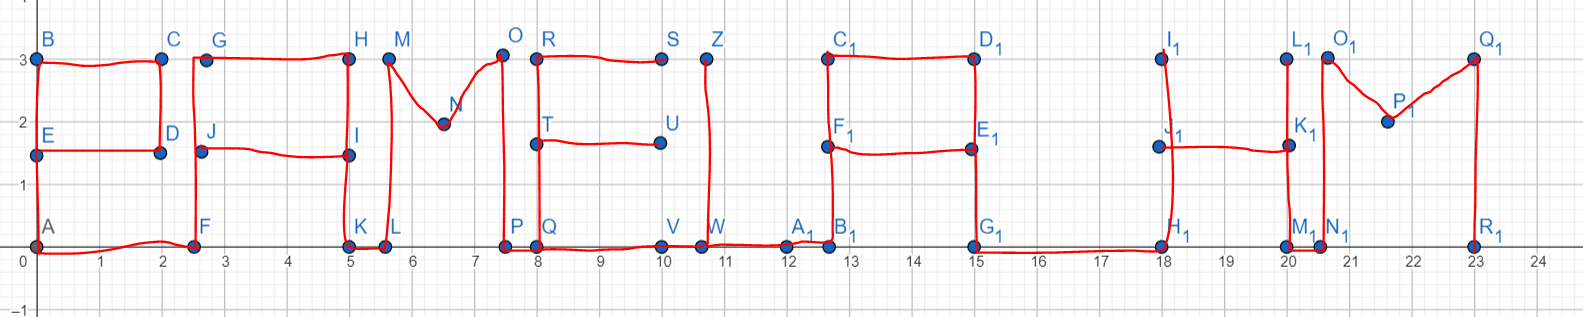

Posteriormente defini los  puntos de referencia (waypoints) que son especificados para formar las letras en el plano XY. Cada letra se encuentra comentada para facilidad de edición.

% Define waypoints
waypoints =[0,0; 0,3; 2,3; 2,1.5; 0,1.5; 0,0; %P
           2.5,0; 2.5,3; 5,3; 5,1.5; 2.5,1.5; 5,1.5; 5,0; %A
           5.5,0; 5.5,3; 6.5,1.5; 7.5,3; 7.5,0; %M
           8,0; 8,3; 10,3; 8,3; 8,1.5; 10,1.5; 8,1.5; 8,0; %E
           10.5,0; 10.5,3; 10.5,0; 12.5,0; %L
           12.5,3; 15,3; 15,1.5; 12.5,1.5; 15,1.5; 15,0; %A
           18,0; %_
           18,3; 18,1.5; 20,1.5; 20,3; 20,0; %H
           20.5,0; 20.5,3; 21.5,1.5; 23,3; 23,0];%M

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

Definida la trayectoria decidí configurar el Pure Pursuit con los parámetros necesarios, la velocidad lineal deseada y la velocidad angular máxima que ayudarán a no tener ruido como los siguientes:

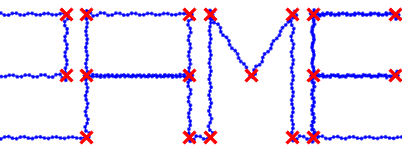                                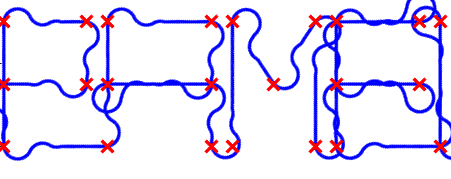

Esto lo logré adecuando la velocidad angular a un valor alto mientras mantenía la velocidad lineal a un valor más bajo debido a que una velocidad angular más alta permite al vehículo realizar giros más rápidos y precisos, lo cual es esencial para seguir la trayectoria de manera efectiva. Al mismo tiempo, una velocidad lineal más baja ayuda a reducir el riesgo de desviarse de la trayectoria deseada y minimiza el ruido en el sistema de control.

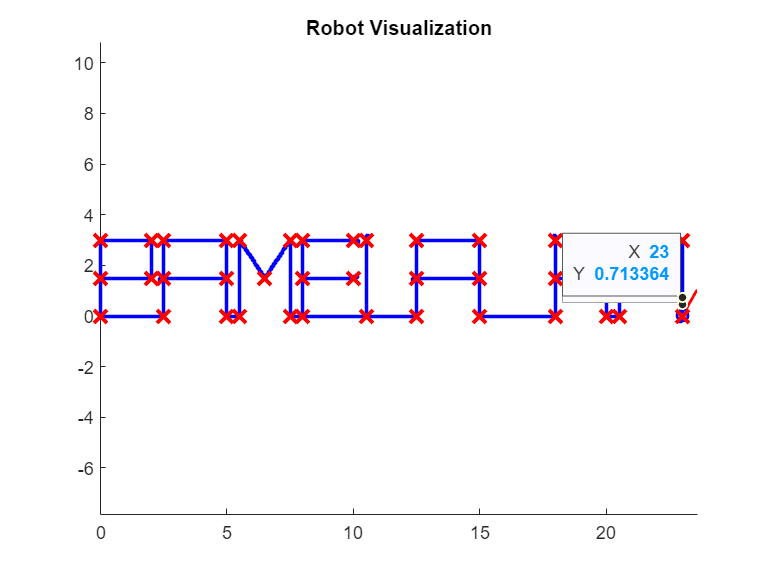

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 500;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
end

**a) ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria recta? ¿Porqué?**

Para obtener una trayectoria recta es necesario hacer que la velocidad angular sea más baja que la velocidad lineal (casi a 0) debido que al eliminar la velocidad angular, el vehículo no girará y avanzará únicamente en línea recta.

**b) ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria curva? ¿Porqué?**

Para una trayectoria curva se mantiene un valor elevado en comparación con la velocidad lineal debido a que gira más rápido que lo que se mueve. El manejo de ambas velocidades permite tener diferentes radios en la trayectoria curva.

**c) ¿Cuál fué el o los parámetros que se modifican para obtener un giro? ¿Porqué?**

Entre más cercana sea la velocidad lineal a 0 más cerrado es el giro del robot, por otro lado la velocidad angular determina la rapidez con la que el vehículo gira sobre su eje

**d) ¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?**

El vector del tiempo define los intervalos de simulación, determinando cuándo se calculan y aplican las actualizaciones de posición y orientación del vehículo. De igual modo ayudan a visualizar la simulación de forma diferente y de poder completar toda la trayectoria definida.

**e) ¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?**

Primero se ajustaron los parámetros de la simulación orientando de forma correcta al carrito, después la definición de los waypoints y por último los valores de las velocidades para que eliminen el ruido generado.